Dla 9 probek

x_train = SensorData9p.Distance_mm'

x_train =      0     2     4     6     8    10    12    14    16


y_train = SensorData9p.Sensor_V'

y_train =     9.5986    9.2948    8.4981    7.2501    5.6701    3.9385    2.2826    0.9604    0.2457



net = feedforwardnet(1, 'traingd');

'feedforwardnet' requires Deep Learning Toolbox.

net = train(net, y_train, x_train);

y_net = net(x_train);
figure;
plot(x_train, y_train)
hold on
plot(x_train, y_net)

Zostala sprawdzona funkcja odwrotna sieci neuronowe

net_inv = feedforwardnet(1);
net_inv = train(net_inv, x_train, y_train);
view(net_inv)



Następnie z wytrenowanej siecie neuronowej zobaczyliśmy wyniki dla wektora. 

x_train = SensorData24p.Distance_mm'

x_train =          0    0.7000    1.4000    2.1000    2.8000    3.5000    4.2000    4.9000    5.6000    6.3000    7.0000    7.7000    8.4000    9.1000    9.8000   10.5000   11.2000   11.9000   12.6000   13.3000   14.0000   14.7000   15.4000   16.1000


y_train = SensorData24p.Sensor_V'

y_train =     9.6444    9.5120    9.3668    9.2611    9.0707    8.7842    8.4320    8.0007    7.5118    7.0018    6.4726    5.8950    5.3150    4.7187    4.1071    3.5747    2.9310    2.3608    1.8257    1.3610    0.9594    0.6241    0.3567    0.2509


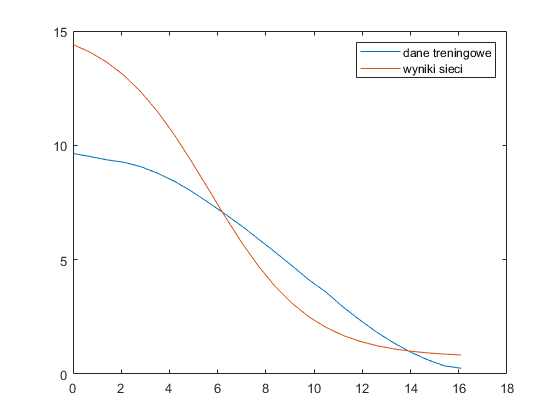


net = feedforwardnet(1);
net = train(net, y_train, x_train);
view(net);

y_net = net(x_train);
figure;
plot(x_train, y_train)
hold on
plot(x_train, y_net)
legend('dane treningowe', 'wyniki sieci')


x_train = SensorData161p.Distance_mm'

x_train =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y_train = SensorData161p.Sensor_V'

y_train =     9.5986    9.5948    9.5898    9.5836    9.5763    9.5678    9.5582    9.5473    9.5353    9.5220    9.5075    9.4918    9.4749    9.4568    9.4374    9.4167    9.3948    9.3717    9.3473    9.3217    9.2948    9.2667    9.2373    9.2067    9.1748    9.1417    9.1073    9.0717    9.0349    8.9968    8.9575    8.9169    8.8752    8.8322    8.7880    8.7426    8.6961    8.6483    8.5994    8.5493    8.4981    8.4457    8.3922    8.3375    8.2818    8.2249    8.1670    8.1080    8.0479    7.9868


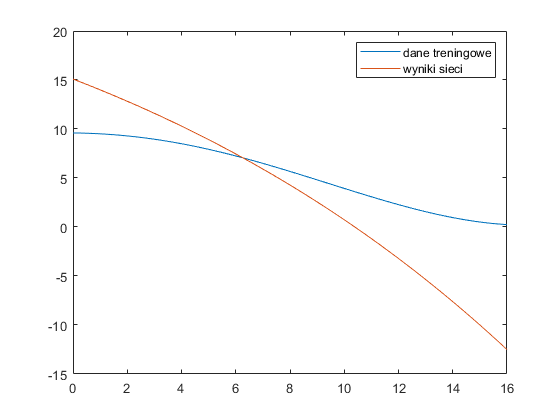


net = feedforwardnet(1, 'trainlm');
net = train(net, y_train, x_train);
view(net);

y_net = net(x_train);
figure;
plot(x_train, y_train)
hold on
plot(x_train, y_net)
legend('dane treningowe', 'wyniki sieci')